# Handling Big Data

Large data sets can be in the form of large files that do not fit into available memory or files that take a long time to process. A large data set also can be a collection of numerous small files. 

MATLAB provide many tools for accessing and processing large data.

## Efficient Use of Memory

### **Use Appropriate Data Storage**

Data classes are of different sizes.

**Choice of numeric Class**

Ex.

- Default floating-point class: `double` (8 bytes)

- Altenatives with limitations on math operations: `single` (4 bytes)

`logical, int8, uint8 `(1)

`int16, uint16 `(2)

`int32, uint32 `(4)

`int64, int64 `(8)

A = zeros(1e6,1,'single');

**Overhead when storing data**

- *Simple numeric arrays* (comprising one `mxArray`) have the least overhead, so we should use them wherever possible.

- *Cell arrays *are comprised of separate `mxArrays` for each element, so cell arrays with many small elements have a large overhead.

- *Structures* require a similar amount of overhead per field. Structures with many fields and small contents have a large overhead and should be avoided. A large array of structures with numeric scalar fields requires much more memory than a structure with fields containing large numeric arrays.

**Importation of data**

When reading data from a binary file with `fread`, it is a common error to specify only the class of the data in the file, and not the class of the data MATLAB uses once it is in the workspace. 

Ex. The default `double` is used even if you are reading only 8-bit values. Should do:

`a = fread(fid, 1e3, 'uint8=>uint8'); `

The default for `'precision'` is `'unit8=>double'`. It means the input values are of the class specified by `unit8`. The class of the output matrix is specified by `double`.

**Sparse Arrays When Possible**

A = eye(100);        % Full matrix with ones on the diagonal
As = sparse(A);       % Sparse matrix with only nonzero elements
whos

### Avoid Temporary Copies of Data

**Avoid Creating Temporary Arrays**

- avoid creating large temporary variables

- clear temporary variables when they are no longer needed

clear A

**Use Nested Functions to Pass Fewer Arguments**

When working with large data sets, be aware that MATLAB makes a temporary copy of an input variable if the called function modifies its value. This temporarily doubles the memory required to store the array, which causes MATLAB to generate an error if sufficient memory is not available.

One way to use less memory in this situation is to use nested functions. A nested function shares the workspace of all outer functions, giving the nested function access to data outside of its usual scope. 

### Reclaim Used Memory

Clear large arrays that are no longer used.

**Save Your Large Data Periodically to Disk**

If the program generates very large amounts of data, consider writing the data to disk periodically. After saving that portion of the data, use the `clear` function to remove the variable from memory and continue with the data generation.

**Clear Old Variables from Memory When No Longer Needed**

When working with a very large data set repeatedly or interactively, clear the old variable first to make space for the new variable. Otherwise, MATLAB requires temporary storage of equal size before overriding the variable.

## Resolve "Out of Memory"

### `Out of memory.`

MATLAB is a 64-bit application that runs on 64-bit operating systems. It returns an error message whenever it requests a segment of memory from the operating system that is larger than what is available.

MATLAB has built-in protection against creating arrays that are too large. By default, MATLAB can use up to 100% of the RAM (not including virtual memory) of your computer to allocate memory for arrays, and if an array would exceed that threshold, then MATLAB returns an error:

% A = rand(1e6,1e6);

### Possible solutions to "out of memory"

**Leverage **`tall`** Arrays**

- Cast the array to a **tall array** if the large array fits in memory, but calculations run out of memory.

- Create a `datastore` from file or folder-based data, and then create a tall array on top of the datastore.

MATLAB works with small blocks of the data at a time, automatically handling all of the data chunking and processing in the background. 

*More to come in next section.*

**Leverage the Memory of Multiple Machines**

Use the Parallel Computing Toolbox™ and Distributed Arrays.

**Load Only as Much Data as You Need**

This is a common problem with loading large flat text or binary files. The `datastore` function can help with this by allowing working with large data sets incrementally. 

*More to come in next section.*

**Increase System Swap Space**

The total memory available to applications on your computer is composed of physical memory (RAM), plus a *page file*, or *swap file*, on disk. The swap file can be very large (for example, 512 terabytes on 64-bit Windows®). The operating system allocates the virtual memory for each process to physical memory or to the swap file, depending on the needs of the system and other processes. Increasing the size of the swap file can increase the total available memory, but also typically leads to slower performance.

**Set the Process Limit on Linux Systems**

The *process limit* is the maximum amount of virtual memory a single process (or application) can address. 64-bit operating systems support a process limit of 8 terabytes. On Linux systems, see the `ulimit` command to view and set user limits including virtual memory.

**Disable Java VM on Linux Systems**

On Linux systems, starting MATLAB without the Java JVM can increase the available workspace memory by approximately 400 megabytes and increase the size of the largest contiguous memory block by about the same amount. To start MATLAB without Java JVM, use the command-line option `-nojvm`.

## Datastore and Tall Arrays

### Datastore

A **datastore** is an object for reading a single file or a collection of files or data. The datastore acts as a repository for data that has the same structure and formatting. For example, each file in a datastore must contain data of the same type (such as numeric or text) appearing in the same order, and separated by the same delimiter.

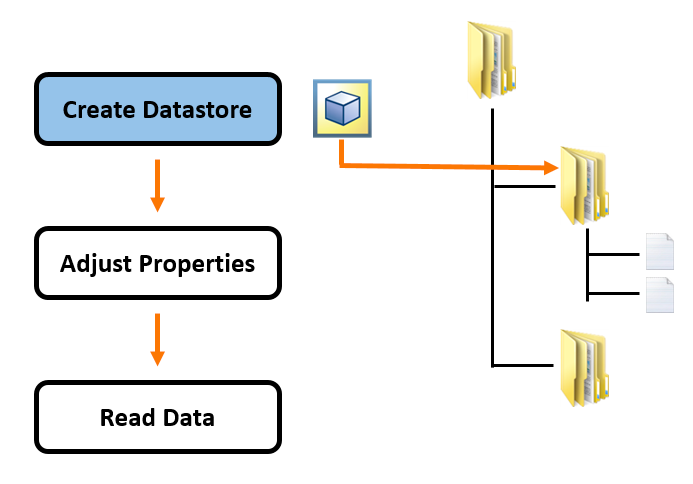

**Create a datastore refering to multiple files**

`DS = datastore(LOCATION,'Type',TYPE)` creates a datastore `DS` based on the `LOCATION` of the data and specifies the type of the datastore. 

The supported types are:

-       '`tabulartext`'     -    For tabular text files

-       '`image`'                  -    For image files

-       '`spreadsheet`'     -    For spreadsheet files

-       '`file`'                    -    For custom format files

-       '`tall`'                    -    For tall data files from tall/write

-       '`keyvalue`'           -    For use with key-value data from mapreduce

-       '`database`'           -    For use with Database Toolbox

**Demo**

Let's revisit the hurricane data.

dat = datastore("data/hurricaneData","Type","tabulartext");
fnames = dat.Files
preview(dat)

**Modify datastore properties**

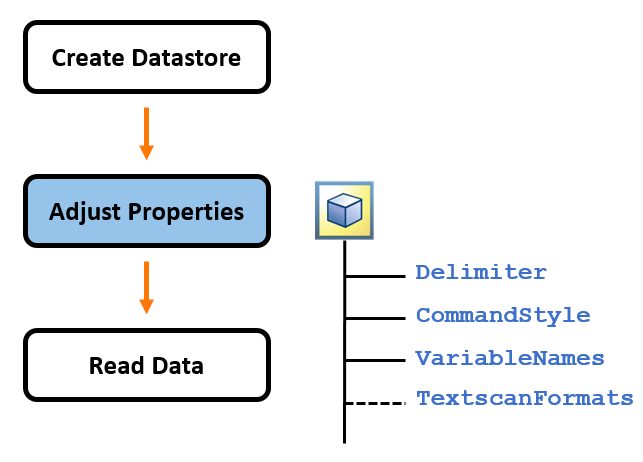

Note that the previous variable names were not read in correctly.

Set the `CommentStyle` property. 

dat.CommentStyle = "##";
preview(dat)

**Read from a datastore**

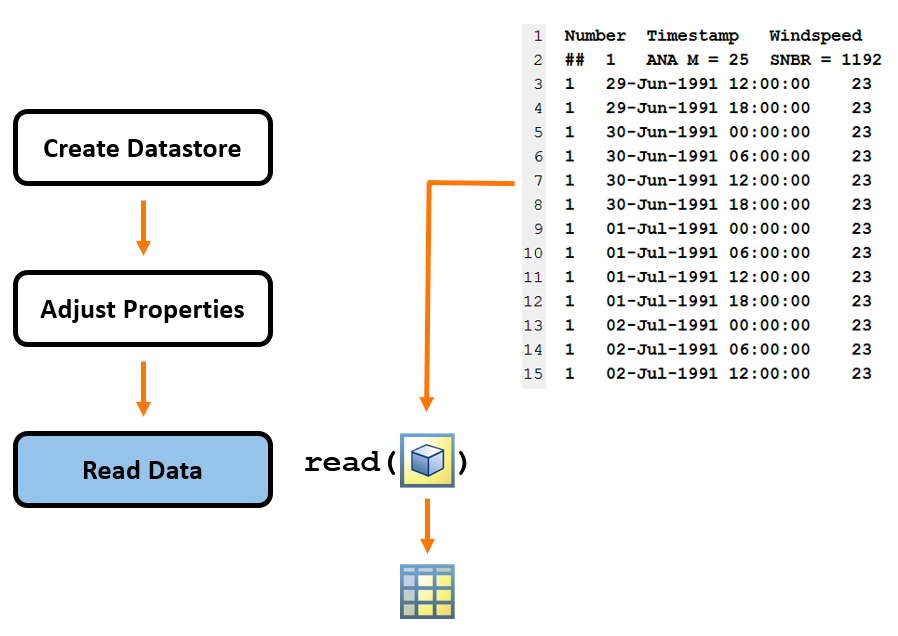

If all of the data in the datastore for the variables of interest fit in memory, we can read it using the `readall` function.

hurrs = readall(dat)

Read the data from the first file, then the second.

hurrs1 = read(dat)
hurrs2 = read(dat)

**Reset**

`reset(ds)` resets the datastore specified by `ds` to the state where no data has been read from it. Resetting allows re-reading from the same datastore.

When data size is large, can choose to read the data in smaller subsets that do fit in memory, using the `read` function. Change the number of rows reading in a time by assigning a new value to the `ReadSize` property.

reset(dat)
dat.ReadSize = 20;
hurrs_small = read(dat)
hurrs_small_next = read(dat)

reset(dat)

### Tall array on top of the datastore

Since the data is not loaded into memory all at once, **tall arrays** can be arbitrarily large in the first dimension (that is, they can have any number of rows). 

Many core operators and functions work the same with tall arrays as they do with in-memory arrays. MATLAB works with small blocks of the data at a time, handling all of the data chunking and processing in the background, so that common expressions, such as `A+B`, work with big data sets.

**Benefit - deferred evaluation: **

- Unlike in-memory arrays, tall arrays typically remain unevaluated until the request to perform the calculations using the `gather` function. 

- MATLAB then combines the queued calculations where possible and takes the minimum number of passes through the data. 

- Request output only when necessary.

**Create tall tables**

tt = tall(dat)

**Create tall arrays**

Extracting variable from a tall table (or timetable) resulting in a tall array of the appropriate underlying data type. 

ws = tt.Windspeed

**Deferred Evaluation**

ws_mean = mean(ws)
ws_std = std(ws)

The result of each operation indicates that the array has not been calculated yet.

**Evaluation with **`gather`

[ws_mean_res,ws_std_res] = gather(ws_mean,ws_std)

Analyze data using histogram

histogram(ws)

## MapReduce

`mapreduce` is a programming technique which is suitable for analyzing large data sets that otherwise cannot fit in the computer’s memory. 

`mapreduce` uses a datastore to process data in small blocks that individually fit into memory. 

- Each block goes through a Map phase, which formats the data to be processed. 

- Then the intermediate data blocks go through a Reduce phase, which aggregates the intermediate results to produce a final result. 

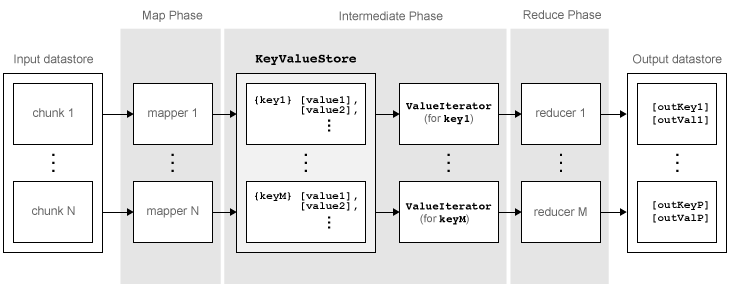

Check out more detailed tutorials from these pages: 

[https://www.mathworks.com/help/matlab/import_export/getting-started-with-mapreduce.html](https://www.mathworks.com/help/matlab/import_export/getting-started-with-mapreduce.html)

[https://www.mathworks.com/help/matlab/import_export/process-big-data-in-matlab-using-mapreduce.html](https://www.mathworks.com/help/matlab/import_export/process-big-data-in-matlab-using-mapreduce.html) 

**Demo**

result = mapreduce(dat, @MeanWsMapFun, @MeanWsReduceFun)
readall(result)

function MeanWsMapFun(data, ~, intermKVStore)
    wspeed = data.Windspeed(~isnan(data.Windspeed));
    sumLenValue = [sum(wspeed)  length(wspeed)];
    add(intermKVStore, 'sumAndLength', sumLenValue);
end

function MeanWsReduceFun(~, intermValIter, outKVStore)
    sumLen = [0 0];
    while hasnext(intermValIter)
        sumLen = sumLen + getnext(intermValIter);
    end
    add(outKVStore, 'Mean', sumLen(1)/sumLen(2));
end

## Database Toolbox

The Database Toolbox provides functions and an app for exchanging data with relational and nonrelational databases. It enables this exchange by automatically converting between database and MATLAB data types.

E.g.

- Import data from and export data to **relational databases** directly within MATLAB. Use knowledge of SQL to exchange data programmatically, or interact with data without using SQL.

- Use the MATLAB Interface to **SQLite** to create, read, and write relational data from SQLite database files without installing or administering database software or drivers.

- Access and import columnar data using the Database Toolbox interface for the **Apache Cassandra** database.

- Store, query, and retrieve unstructured and structured data using the Database Toolbox interface for **MongoDB**.

- Explore, manage, and store graph data in **Neo4j** databases using the MATLAB interface to Neo4j. Perform graph network analysis with or without existing knowledge of the Cypher® graph query language.

More information on the toolbox here: [https://www.mathworks.com/products/database.html](https://www.mathworks.com/products/database.html) 

** Contents of this lecture are adapted from MATLAB documention available at *[https://www.mathworks.com/help/matlab/large-files-and-big-data.html](https://www.mathworks.com/help/matlab/large-files-and-big-data.html) *and the tutorials in *[*MATLAB for Data Processing and Visualization*](https://matlabacademy.mathworks.com/R2020b/portal.html?course=mlvi)*.*